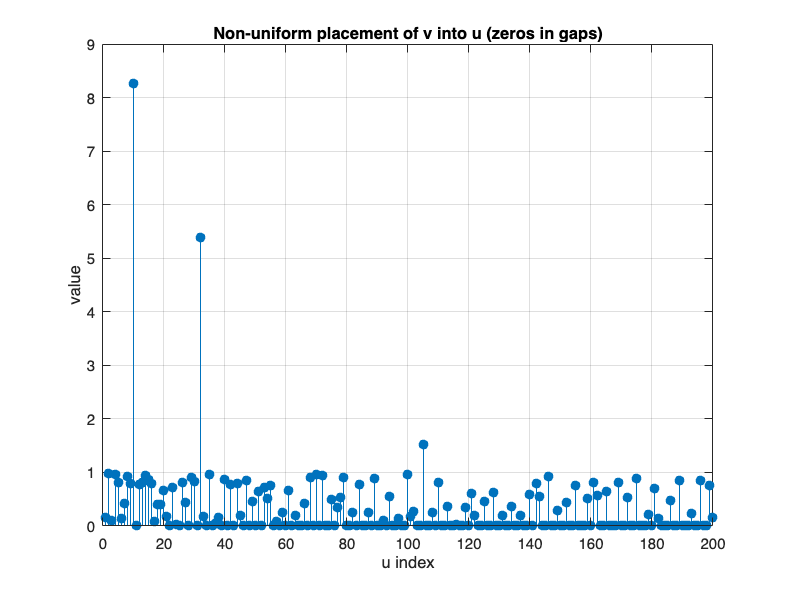


% Given v of length 100
% v = rand(100,1);                 % example data
% Nv = numel(v);
rng(0)

% generate 
M = 100;                      % length
p = 0.1;                     % proportion of large values (10%)
nz = round(p*M);
largeVals = randperm(M, nz);  % positions for large values
v = rand(M,1);          % start with tiny values
v(largeVals) = rand(length(largeVals),1)*10;  % inject larger values
N = 200;

% Create a nonlinear index map from v -> u
% Use a convex/nonlinear schedule for gradual non-uniform spacing.
% For example: compress early indices (dense), stretch later (sparse)
t = linspace(0,1,M);            % normalized positions of v
g = t.^1.8;                      % warping function (adjust exponent for degree of non-uniformity)
idx_u = round( 1 + g*(N-1) );   % map to integer indices in u
idx_u = unique(idx_u,'stable');  % avoid collisions (keeps first occurrence)

% If collisions reduced the count, fill remaining with nearest free slots
while numel(idx_u) < M
    % find nearest available index positions
    allIdx = 1:N;
    free   = setdiff(allIdx, idx_u);
    % pick some free ones (e.g., uniformly from remaining)
    need   = M - numel(idx_u);
    idx_u  = [idx_u, free(round(linspace(1,numel(free),need)))];
    idx_u  = unique(idx_u,'stable');
end
idx_u = idx_u(1:M);             % ensure exactly Nv placements

% Build u, zeros in gaps
% u = zeros(N,1);
% u(idx_u) = v;

Phi = zeros(N,1);
Phi(idx_u) = true;
Phi = diag(Phi);

x = zeros(N,1);
x(idx_u) = v;
tidx = 1:N;
x(~ismember(tidx,idx)) = rand(M,1);


% Visualize index spacing
figure; 
stem(Phi * x,'filled'); grid on;
title('Non-uniform placement of v into u (zeros in gaps)');
xlabel('u index'); ylabel('value');

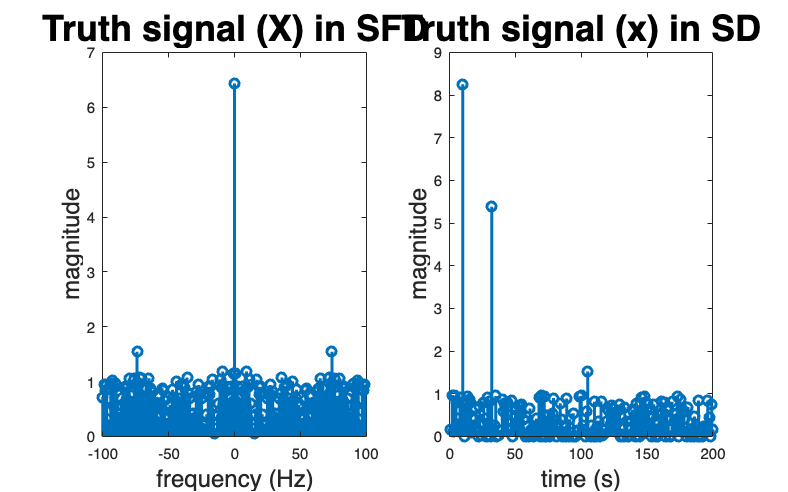

% formulate the measured signal y = Ax + n where A is the
% system or sensing matrix, y is the measurement, x is the
% signal and n is the noise

% define the sparsifying transformation
F = (1/sqrt(N)) * fft(eye(N));
Psi = F;

% define the measurement matrix
A = Psi * Phi;

% calculate the measurement
Y = A * x;
X = Psi * x;

f=figure;
subplot(1,2,1)
stem(-N/2:N/2-1, abs(fftshift(X)), 'LineWidth',2)
title('Truth signal (X) in SFD','FontSize',24)
xlabel('frequency (Hz)','FontSize',16)
ylabel('magnitude','FontSize',16)

subplot(1,2,2)
stem(x, 'LineWidth',2)
title('Truth signal (x) in SD','FontSize',24)
xlabel('time (s)','FontSize',16)
ylabel('magnitude','FontSize',16)
set(gcf, 'Position', get(0, 'Screensize'));

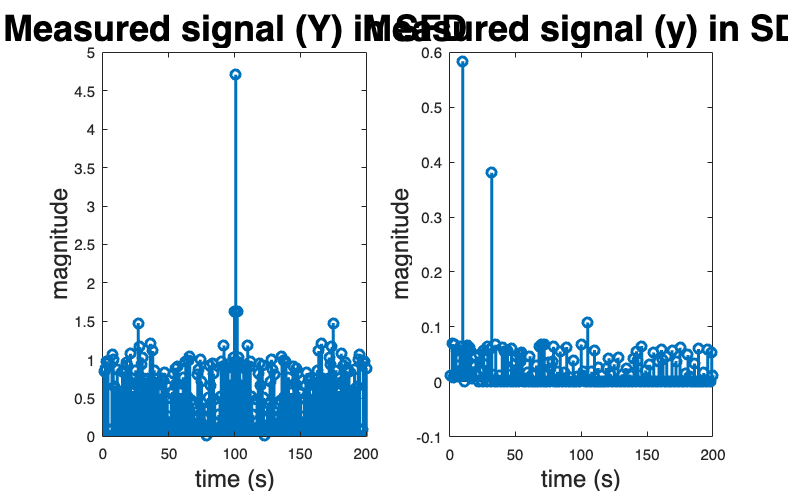

figure
subplot(1,2,1)
stem(abs(fftshift(Y)), 'LineWidth',2)
title('Measured signal (Y) in SFD','FontSize',24)
xlabel('time (s)','FontSize',16)
ylabel('magnitude','FontSize',16)
set(gcf, 'Position', get(0, 'Screensize'));
subplot(1,2,2)
stem(ifft(Y), 'LineWidth',2)
title('Measured signal (y) in SD','FontSize',24)
xlabel('time (s)','FontSize',16)
ylabel('magnitude','FontSize',16)

set(gcf, 'Position', get(0, 'Screensize'));

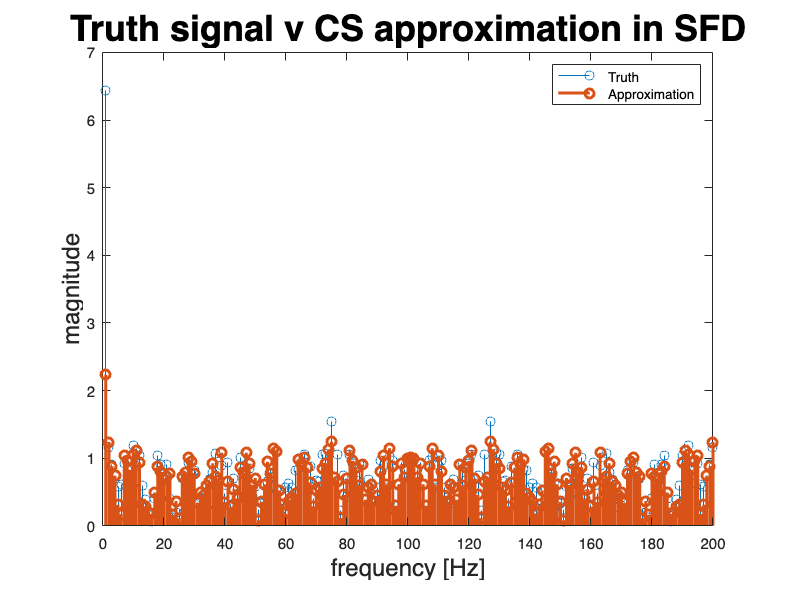

% Apply compressive sensing techniques using the orthogonal
% matching pursuit method which assumes the columns of A
% (iid Gaussian) are roughly orthogonal. The goal is to
% determine the basis vector in A that is overlaps the most
% with the measurement. This overlap is determined by an
% inner product between the measurement and each vector,
% resulting in the transformation coefficients. The greater
% the magnitude of the coefficient, the greater the overlap.
% Select the basis vector in A with the greatest inner
% product, and solve for an approximation of signal by
% minimizing || y - Ax ||_{2}^{2} using the least squares method 

% initialize the array containing the approximate non-zero
% indices
Lambda = []; x_hat = zeros(N,1);

% for now, assume we have knowledge of the number of
% nonzeros
r = Y;
for i = 1:nz*2+1

    % inner product of the measurement and basis vectors
    c = A'* r;

    % find the index that maximizes the inner product
    [~, l] = max(abs(c));
    Lambda = [Lambda; l];

    % use this basis vector to calculate the least squares
    % solution
    x_hat(Lambda) = inv(A(:,Lambda)'*A(:,Lambda))*A(:,Lambda)'*Y;
    r = Y - A * x_hat;
end

X_hat = Psi * x_hat;

f = figure;
stem(1:size(X,1),abs(X), 'DisplayName', 'Truth')
hold on
stem(1:size(X_hat,1),abs(X_hat),'DisplayName','Approximation', 'LineWidth',2)
title('Truth signal v CS approximation in SFD','FontSize',24)
xlabel('frequency [Hz]','FontSize',16)
ylabel('magnitude','FontSize',16)
legend

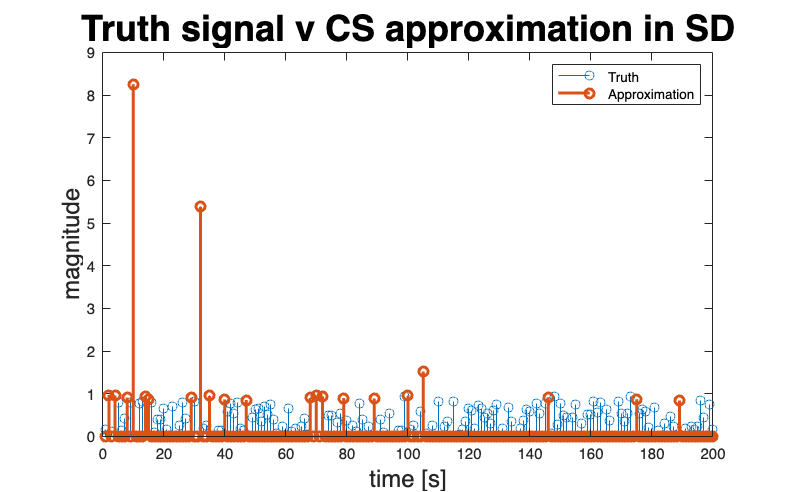


f = figure;
stem(1:size(x,1),x, 'DisplayName', 'Truth')
hold on
stem(1:size(x_hat,1),real(x_hat),'DisplayName','Approximation','LineWidth',2)
title('Truth signal v CS approximation in SD','FontSize',24)
xlabel('time [s]','FontSize',16)
ylabel('magnitude','FontSize',16)
legend
set(gcf, 'Position', get(0, 'Screensize'));
saveas(f,'plots/recon_fft.png')